# **IE 415**

# **Control Of Autonomus System**

### Name:- Hitarth Bhatt

#### Roll No. :- 202201024

## Simulation and Control of Autonomous QCar System 

This project simulates the motion of a Quanser QCar in a Simscape environment, using SLAM trajectory data for autonomous navigation. It integrates LQR control and Kalman Filtering for precise trajectory tracking and state estimation. The QCar follows a SLAM-generated reference path by dynamically adjusting steering angles and wheel velocities, modeled with a state-space representation. The project demonstrates autonomous vehicle control, combining motion planning, state estimation, and realistic visualization.

## Import URDF file to create Simscape Multibody model

%% Import URDF and Set Up the Model
addpath([pwd filesep 'Geometry']); % Add geometry path

% Import the URDF model
[mdl_h] = smimport('sm_quanserQCar.urdf', 'ModelName', 'sm_quanserQCar_1');
mdl_name = getfullname(mdl_h);

## Update diagram, note initial robot position

% Update model to visualize it
set_param(mdl_h, 'SimulationCommand', 'update');
disp(['Model ', mdl_name, ' has been successfully imported.']);

Model sm_quanserQCar_1 has been successfully imported.


## Mechanics Explorer

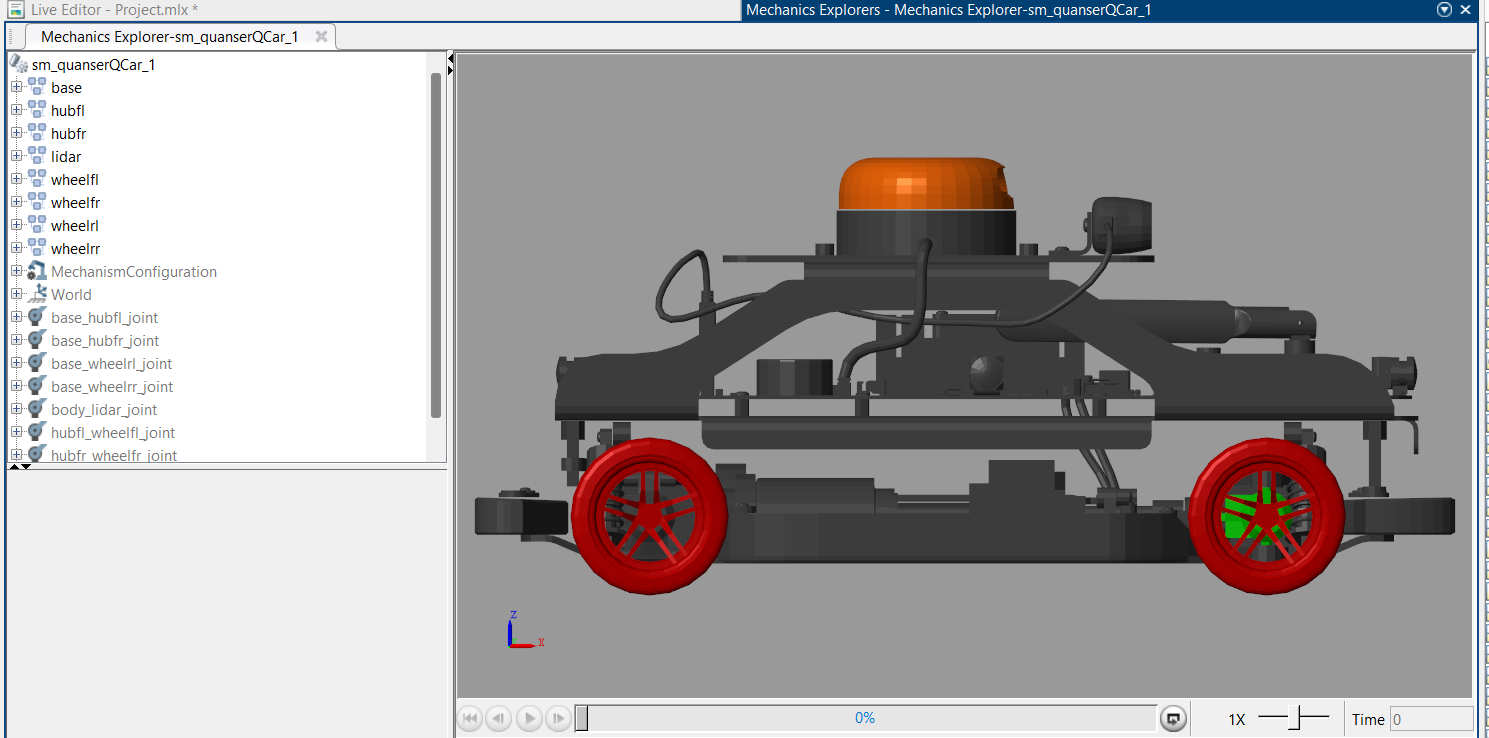

## Simulink Model:

## 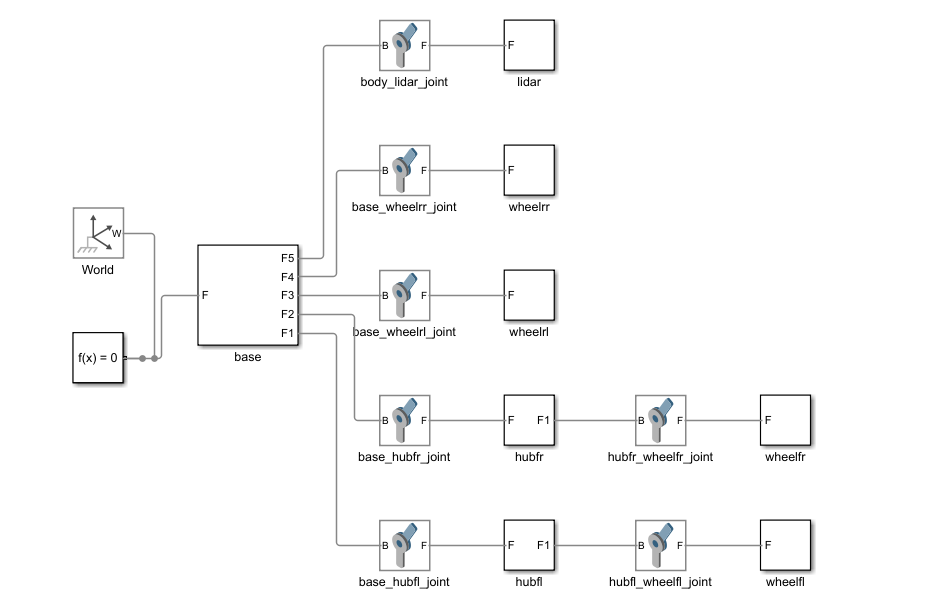 

## **State-Space Modeling**

The QCar's dynamic behavior is represented using a state-space model, capturing its states, inputs, and outputs. The model is defined with system matrices AA, BB, CC, and DD, ensuring controllability for effective control design. An LQR controller is implemented to compute optimal control inputs, balancing trajectory tracking accuracy and energy efficiency. The model is integrated into the simulation to predict system behavior and guide the QCar along the desired trajectory.

%% Define State-Space Model
A = [0 1 0 0;
     0 -1 0 0.5;
     0 0 0 1;
     0 0.5 0 -1]; 
B = [0 0;
     1 0;
     0 0;
     0 1]; 
C = eye(4); 
D = zeros(4, 2); 

% Check controllability
Co = ctrb(A, B);
if rank(Co) < size(A, 1)
    error('System is not controllable.');
else
    disp('System is controllable.');
end

System is controllable.


## **LQR Controller**

An LQR controller is designed to optimize the QCar's trajectory tracking by minimizing a cost function that balances state deviations and control effort. The controller uses the state-space model to compute optimal control inputs, dynamically adjusting steering and wheel velocities. The LQR gains are tuned for stability and accuracy, enabling the QCar to efficiently follow the desired SLAM trajectory.

%% Define LQR Parameters
Q = diag([10, 1, 10, 1]);
R = eye(2);


K = lqr(A, B, Q, R);
disp('LQR Gain Matrix:');

LQR Gain Matrix:


disp(K);

    3.1623    1.9232   -0.0000    0.3290
    0.0000    0.3290    3.1623    1.9232



## **Simulating QCar Dynamics**

The QCar's dynamics are simulated using its state-space model and the computed LQR control inputs. The simulation iteratively updates the QCar's states, including position, velocity, and orientation, based on the control signals. The results are recorded and visualized to evaluate the QCar's ability to follow the SLAM trajectory, providing insights into the system's performance and stability.

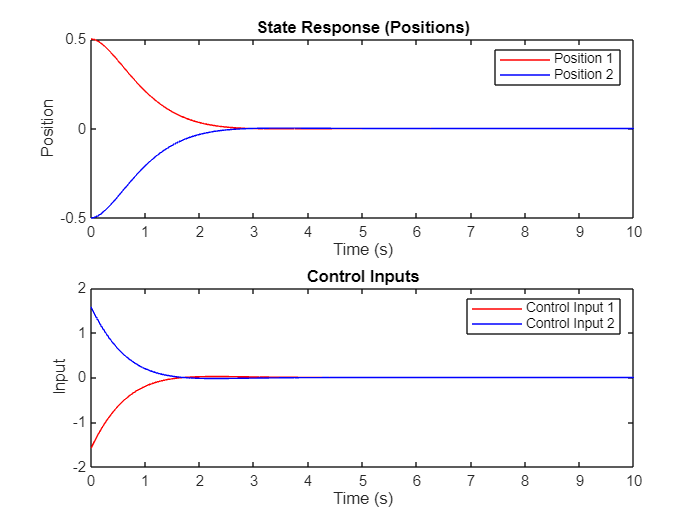

%% Simulate System with LQR Control

T = 10; 
dt = 0.01; 
time = 0:dt:T;

x = [0.5; 0; -0.5; 0]; 
u = [0; 0]; 

x_hisxt = zeros(4, length(time));
u_hist = zeros(2, length(time));


for i = 1:length(time)
    u = -K * x;

    x_dot = A * x + B * u; 
    x = x + x_dot * dt; 

    x_hist(:, i) = x;
    u_hist(:, i) = u;
end

% Plot Results
figure;
subplot(2, 1, 1);
plot(time, x_hist(1, :), 'r', 'DisplayName', 'Position 1');
hold on;
plot(time, x_hist(3, :), 'b', 'DisplayName', 'Position 2');
title('State Response (Positions)');
xlabel('Time (s)');
ylabel('Position');
legend;

subplot(2, 1, 2);
plot(time, u_hist(1, :), 'r', 'DisplayName', 'Control Input 1');
hold on;
plot(time, u_hist(2, :), 'b', 'DisplayName', 'Control Input 2');
title('Control Inputs');
xlabel('Time (s)');
ylabel('Input');
legend;

## Kalman Filter for an State Estimation

A Kalman Filter is implemented for state estimation, combining the QCar's dynamic model with noisy measurements. It predicts the system's states and updates them using sensor data to minimize estimation errors. This ensures accurate tracking of the QCar's position and velocity, enabling reliable control and trajectory-following performance. The estimated states are compared with true values to validate the filter's effectiveness.

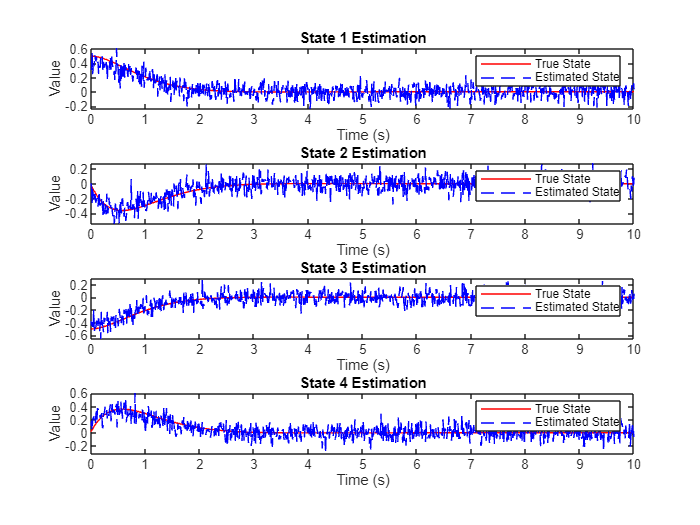

%% Kalman Filter for State Estimation
Q_kal = 0.1 * eye(4); 
R_kal = 0.01 * eye(4); 


x_est = [0; 0; 0; 0];
P = eye(4);

x_est_hist = zeros(4, length(time));


for i = 1:length(time)
    u = u_hist(:, i);

    x_pred = A * x_est + B * u; % Use the correct 2x1 control vector
    P_pred = A * P * A' + Q_kal;

    z = x_hist(:, i) + sqrt(R_kal) * randn(4, 1); 
    K_kal = P_pred * C' / (C * P_pred * C' + R_kal); 
    x_est = x_pred + K_kal * (z - C * x_pred); 
    P = (eye(4) - K_kal * C) * P_pred; 

    % Record history
    x_est_hist(:, i) = x_est;
end

figure;
for state_idx = 1:4
    subplot(4, 1, state_idx);
    plot(time, x_hist(state_idx, :), 'r', 'DisplayName', 'True State');
    hold on;
    plot(time, x_est_hist(state_idx, :), 'b--', 'DisplayName', 'Estimated State');
    title(['State ', num2str(state_idx), ' Estimation']);
    xlabel('Time (s)');
    ylabel('Value');
    legend;
end

## SLAM Planning

SLAM planning generates a smooth trajectory for the QCar by interpolating waypoints. The planned trajectory provides reference positions and headings for the QCar to follow. Steering angles and wheel velocities are calculated based on this trajectory, ensuring smooth and precise navigation. The SLAM-generated path is used to evaluate the QCar's ability to track and adapt to dynamic navigation tasks.

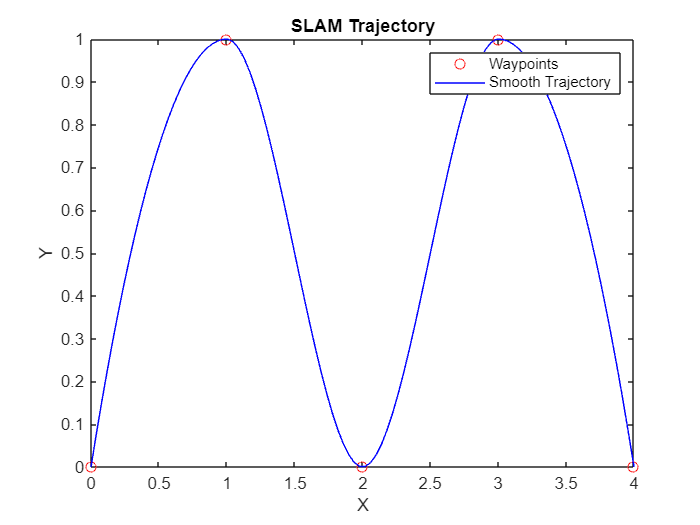

% Define waypoints for the trajectory
waypoints = [0 0; 1 1; 2 0; 3 1; 4 0]; 

% Interpolate the trajectory for smooth motion
traj_time = linspace(0, T, size(waypoints, 1)); 
time_smooth = linspace(0, T, 100); 
x_smooth = interp1(traj_time, waypoints(:, 1), time_smooth, 'pchip'); 
y_smooth = interp1(traj_time, waypoints(:, 2), time_smooth, 'pchip'); 


figure;
plot(waypoints(:, 1), waypoints(:, 2), 'ro', 'DisplayName', 'Waypoints');
hold on;
plot(x_smooth, y_smooth, 'b-', 'DisplayName', 'Smooth Trajectory');
title('SLAM Trajectory');
xlabel('X');
ylabel('Y');
legend;

## Conclusion

This project successfully integrates state-space modeling, LQR control, Kalman filtering, and SLAM planning to simulate and control the motion of a Quanser QCar in a Simscape environment. The state-space representation captures the system's dynamics and provides a foundation for control design. The LQR controller ensures optimal trajectory tracking by minimizing state deviations and control effort, while the Kalman filter enhances accuracy through robust state estimation in the presence of noisy measurements. SLAM planning generates a smooth reference trajectory, guiding the QCar to follow waypoints effectively. The simulation demonstrates the QCar's ability to adapt to dynamic navigation tasks, combining precise control and realistic visualization. This approach highlights the potential of combining advanced control strategies and planning techniques for autonomous vehicle simulations, providing a robust framework for future development and experimentation.

## References

- Industrial Robot Simscape: QuanserQCar: [Model Link](https://github.com/mathworks/Industrial-Robots-Simscape/tree/master/Robots/quanserQCar)

## Files

- GitHub Repository Of Project: [GitHub Repository Link](https://github.com/HappyJoddd/IE415_Project_QuanserQCar)

- Demo Video Link: [Demo Video](https://drive.google.com/file/d/1uXP-fxQSDiXWB0LWhgYh7_Joh1U7_a3F/view?usp=sharing)

*Copyright 2021-2024 The MathWorks, Inc.*